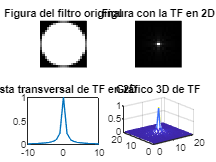

clc
clear all

%Actividad 1
figure(1)
Fc = fspecial('disk',10);
subplot(2,2,1)
imshow(Fc,[])
title("Figura del filtro original")

TF = fft2(Fc);
TFC = fftshift(TF);
subplot(2,2,2)
M = abs(TFC);
imshow(M,[])
title("Figura con la TF en 2D")

[I_row, ~] = size(M);
I_M = M(round(I_row/2),:);
fs = -round(length(I_M)/2-1):round(length(I_M)/2-1);
x = M(11,:);
subplot(2,2,3)
plot(fs, x)
title("Vista transversal de TF en 2D")

subplot(2,2,4)
mesh(M)
title("Gráfico 3D de TF")

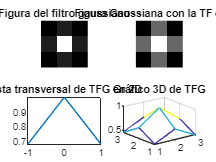


%Actividad 2
figure (2)
FG = fspecial('gaussian');
subplot(2,2,1)
imshow(FG,[])
title("Figura del filtro gaussiano")

TFG = fft2(FG);
TFG2 = fftshift(TFG);
subplot(2,2,2)
P = abs(TFG2);
imshow(P,[])
title("Figura Gaussiana con la TF en 2D")

[I_row, ~] = size(P);
I_P = P(round(I_row/2),:);
fsg = -round(length(I_P)/2-1):round(length(I_P)/2-1);
x1 = P(2,:);
subplot(2,2,3)
plot(fsg, x1)
title("Vista transversal de TFG en 2D")

subplot(2,2,4)
mesh(P)
title("Gráfico 3D de TFG")

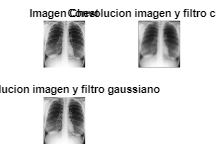


%Actividad 3
figure (3)
imagen= imread('Chest.jpg');
subplot(2,2,1)
imshow(imagen)
title('Imagen Chest')

I1=imfilter(imagen, Fc, 'conv');
subplot(2,2,2)
imshow(I1)
title("Convolucion imagen y filtro circular ")

I2=imfilter(imagen, FG, 'conv');
subplot(2,2,3)
imshow(I2)
title("Convolucion imagen y filtro gaussiano ")


%Actividad 4
TFC=fft2(imagen);
[Rows Cols] = size(TFC)

Rows = 544

Cols = 483

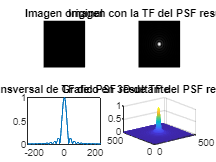


PSF_1 = fft2(Fc, 544, 483);
PSF_2 = fft2(FG, 544, 483);

MTF_1 = abs(PSF_1); 
MTF_2 = abs(PSF_2); 

MTFT= MTF_1 .* MTF_2;
MTFC = fftshift(MTFT);
PSFR = ifft2(MTFT);
PSFr = fftshift(PSFR);

figure (4)
subplot(2,2,1)
imshow(PSFr)
title('Imagen original')

subplot(2,2,2)
n= abs(MTFC);
imshow(n,[])
title('Imagen con la TF del PSF resultante')

y = n(272,:);
[I_row3, ~] = size(n);
I_M3 = n (round(I_row3/2), : );
FSS = (-round((length(I_M3)/2)-1):1:round(length(I_M3)/2)-1);
subplot(2,2,3)
plot(FSS,y)
title('Vista transversal de TF del PSF resultante')

subplot(2,2,4)
mesh(n)
title('Grafico en 3D de TF del PSF resultante')